clear; close; clc;
%flight condtino for cruise
load('CARTRIDGE_105_MILLIMETER_HERA_M927.mat')

d = CARTRIDGE_105_MILLIMETER_HERA_M927.Hydrolic_Diameter;
l = CARTRIDGE_105_MILLIMETER_HERA_M927.Projectile_Length;
       

S_ref = pi*d/4;
Weight_50 = (CARTRIDGE_105_MILLIMETER_HERA_M927.Projectile_Mass - CARTRIDGE_105_MILLIMETER_HERA_M927.Propellant_Mass/2) * 9.81; % wieght at 50% fuel load
Lift = Weight_50;

isCoasting = true; % we are doing both true and false (this should not be defined here)

%height = 1000; % we will do this for various altitudes. not yet implemented
height = 0; % we will do this for various altitudes. not yet implemented



% we will compute velocity from the qbar as qbar is our independent
% variable
% %for various velocities (varying q_bar)
% Vmin = 100; Vmax = 680; %m/s
% Vstep = 1; %m/s

%V_list = Vmin:Vstep:Vmax % velocity range
%Vsteps = length(V_list);

% initialize looop solution arrays
nPoints = 1000

nPoints = 1000


q_bars = logspace(2,4,nPoints);
q_bars = linspace(2,4,nPoints);

alpha_optimum = zeros(nPoints,0);
V_list = zeros(nPoints,0);


L_over_D_1g = zeros(nPoints,0);
L_over_D_1g_powered = zeros(nPoints,0);

for j = 1:nPoints
    q = q_bars(j);

    [~,a,~,rho] = atmosisa(height);
    V = sqrt(2*q/rho);
    V_list(j) = V;
    M = V/a;
    
    C_L = Lift/(S_ref*q);
    
    %newton raphson to converge on the optimal value for alpha for lift=weight
    alpha_guess = .001;
    for i = 1:10000
        C_N = normalForceCoeff_liftingBody(l,d/2,d/2,0,alpha_guess);
        C_N_alpha = normalForce_withRespectTo_alpha(d/2,d/2,0);
        alpha_guess = alpha_guess - (C_N-C_L)/C_N_alpha;
    end
    
    alpha_optimum(j) = alpha_guess;
    L_over_D_1g(j) = lift_to_drag_ratio_body(normalForceCoeff_liftingBody(l,d/2,d/2,0,alpha_optimum(j)),dragCoeff_zeroLift_body(M,q,CARTRIDGE_105_MILLIMETER_HERA_M927.Projectile_Length,CARTRIDGE_105_MILLIMETER_HERA_M927.Nose_Length,d,CARTRIDGE_105_MILLIMETER_HERA_M927.Nose_Tip_Diameter,CARTRIDGE_105_MILLIMETER_HERA_M927.Boattail_Diameter,CARTRIDGE_105_MILLIMETER_HERA_M927.Nozzle_Exit_Area,isCoasting),alpha_optimum(j));
    % only impact of thrust is here (there seems to be no impact on L/D)
    L_over_D_1g_powered(j) = lift_to_drag_ratio_body(normalForceCoeff_liftingBody(l,d/2,d/2,0,alpha_optimum(j)),dragCoeff_zeroLift_body(M,q,CARTRIDGE_105_MILLIMETER_HERA_M927.Projectile_Length,CARTRIDGE_105_MILLIMETER_HERA_M927.Nose_Length,d,CARTRIDGE_105_MILLIMETER_HERA_M927.Nose_Tip_Diameter,CARTRIDGE_105_MILLIMETER_HERA_M927.Boattail_Diameter,CARTRIDGE_105_MILLIMETER_HERA_M927.Nozzle_Exit_Area,false),alpha_optimum(j));
end

%cruise_results = {alpha_optimum, L_over_D_1g, L_over_D_1g_powered, q_bars} % as cell array
cruise_result.alpha_optimum = alpha_optimum;
cruise_result.alpha_optimum = q_bars;
cruise_result.L_over_D_1g = L_over_D_1g;
cruise_result.L_over_D_1g_powered = L_over_D_1g_powered;
cruise_result.alt = height;
%cruise_results = {cruise_result} % something like this to madd my results
%to the cell array

alpha_optimum

alpha_optimum = 1.0e+06 *

    3.7385    3.7112    3.7104    3.7071    3.7071    3.7022    3.7029    3.7071    3.7071    3.6791    3.6804    3.6757    3.6757    3.6714    3.6698    3.6757    3.6757    3.6757    3.6481    3.6497    3.6442    3.6442    3.6393    3.6233    3.6442    3.6442    3.6176    3.6181    3.6181    3.6128    3.6128    3.6082    3.6070    3.6128    3.6128    3.5882    3.5874    3.5845    3.5814    3.5814    3.5768    3.5754    3.5814    3.5814    3.5546    3.5549    3.5534    3.5500    3.5500    3.5451


L_over_D_1g

L_over_D_1g =     0.0524  -18.4882   -1.0447   -0.0143   -1.9269   -4.3572   -0.2744    1.8936    1.5329    0.0382   -0.6469    1.0842    0.7144    1.1120    0.9695    1.1028    0.0723    0.3468   -1.3307   -7.3619    0.0811   -2.1515   -6.7998   -0.2798    1.5423    0.8659    0.9428    1.0601    0.5004   -0.0768    0.1984    1.1599    0.7992    2.0966    1.6207   -0.6200   -2.8164   -3.4572    0.9304   -1.4147    0.8869    1.9926    1.4416    1.1643   -0.5172   -0.7253   -0.0829    0.2889   -6.5525    7.4394


L_over_D_1g_powered

L_over_D_1g_powered =     0.0524  -18.4748   -1.0446   -0.0143   -1.9268   -4.3567   -0.2744    1.8940    1.5332    0.0382   -0.6469    1.0842    0.7145    1.1120    0.9695    1.1029    0.0724    0.3469   -1.3307   -7.3601    0.0811   -2.1515   -6.7983   -0.2798    1.5423    0.8661    0.9428    1.0602    0.5005   -0.0768    0.1984    1.1599    0.7992    2.0968    1.6210   -0.6200   -2.8162   -3.4569    0.9304   -1.4147    0.8869    1.9928    1.4416    1.1646   -0.5172   -0.7253   -0.0829    0.2889   -6.5511    7.4427


q_bars

q_bars =     2.0000    2.0020    2.0040    2.0060    2.0080    2.0100    2.0120    2.0140    2.0160    2.0180    2.0200    2.0220    2.0240    2.0260    2.0280    2.0300    2.0320    2.0340    2.0360    2.0380    2.0400    2.0420    2.0440    2.0460    2.0480    2.0501    2.0521    2.0541    2.0561    2.0581    2.0601    2.0621    2.0641    2.0661    2.0681    2.0701    2.0721    2.0741    2.0761    2.0781    2.0801    2.0821    2.0841    2.0861    2.0881    2.0901    2.0921    2.0941    2.0961    2.0981


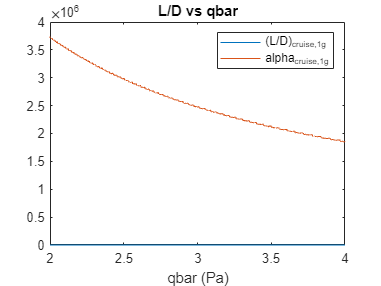


% plot trend of l/d and alpha
plot(q_bars,[L_over_D_1g; alpha_optimum]); title("L/D vs qbar"); xlabel("qbar (Pa)"); legend(["(L/D)_{cruise,1g}", "alpha_{cruise,1g}"]);

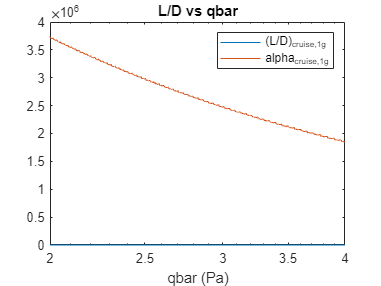

semilogx(q_bars,[L_over_D_1g; alpha_optimum]); title("L/D vs qbar"); xlabel("qbar (Pa)"); legend(["(L/D)_{cruise,1g}", "alpha_{cruise,1g}"]);

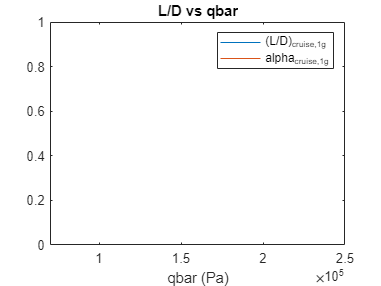


%region of intrest
plot(q_bars,[L_over_D_1g; alpha_optimum]); title("L/D vs qbar"); xlabel("qbar (Pa)"); legend(["(L/D)_{cruise,1g}", "alpha_{cruise,1g}"]); xlim([.7e5, 2.5e5]);

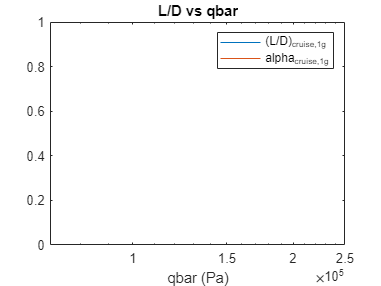

%log plot to match fleeman
semilogx(q_bars,[L_over_D_1g; alpha_optimum]); title("L/D vs qbar"); xlabel("qbar (Pa)"); legend(["(L/D)_{cruise,1g}", "alpha_{cruise,1g}"]); xlim([.7e5, 2.5e5]);

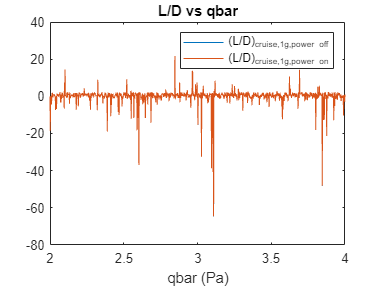



%compare powered and unpowerd
plot(q_bars,[L_over_D_1g; L_over_D_1g_powered]); title("L/D vs qbar"); xlabel("qbar (Pa)"); legend(["(L/D)_{cruise,1g,power off}", "(L/D)_{cruise,1g,power on}"]); % this plot is unintresting as drag reduction is negligeable